# MATLAB Olympiade 2022 

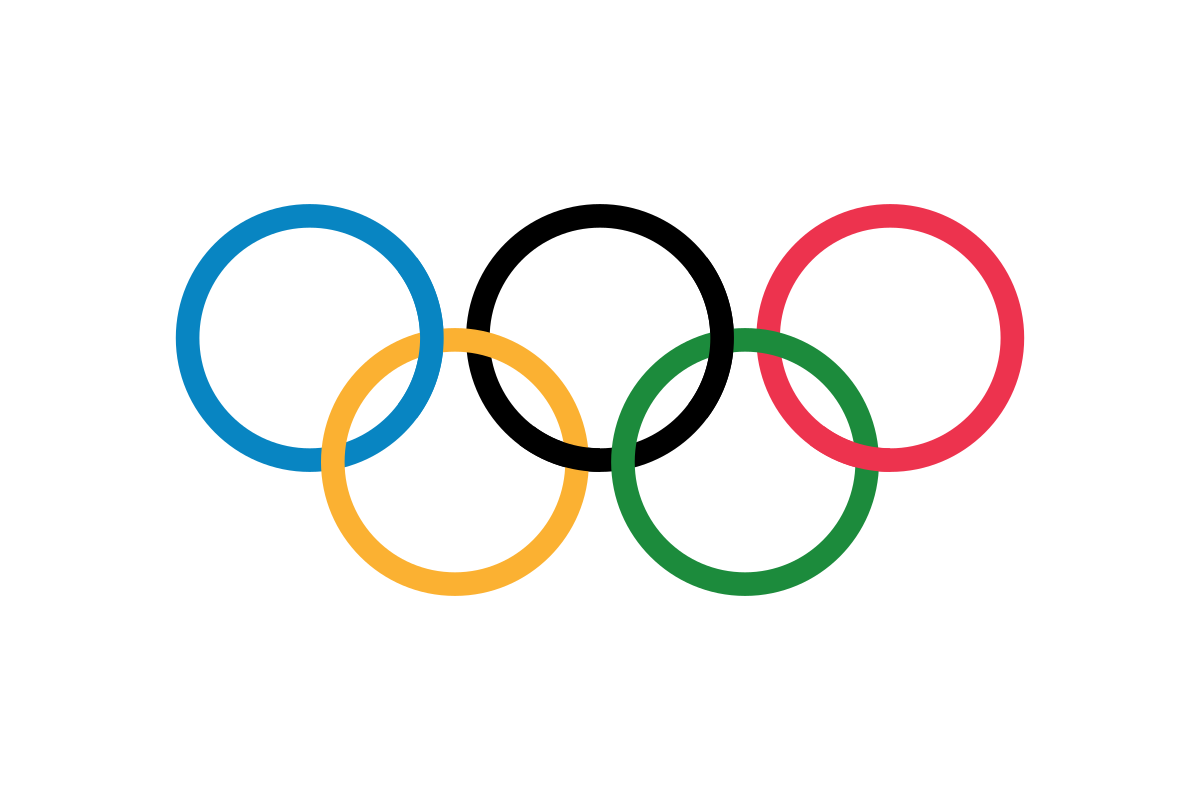

Willkommen zur MATLAB-Olympiade! 

Dieses Skript fasst alle Aufgaben zusammen. Bearbeitet die Aufgaben bitte in den jeweiligen Funktionen. Wenn ihr mit einer Aufgabe fertig seid, könnt ihr in dieses Skript zurückkehren und entweder das ganze Skript ausführen ("Run", grüner Pfeil) oder nur den jeweiligen Abschnitt der Aufgabe einzeln ausführen ("Run Section", Symbol neben "Run").

Im letzten Abschnitt ist ein simpler Aufgaben-Checker, der prüft, ob die Funktionen auch das richtige zurückgeben . Der Aufgaben-Checker prüft dagegen nicht, wie ihr die Funktionen implementiert habt. Wenn ihr das ganze Skript oder eben nur den letzten Abschnitt ausführt (oder nur die Funktion `funktionscheck()` im Command Window aufruft), seht ihr das richtig/falsch-Ergebnis für jede Aufgabe (mit Ausnahme der Aufgabe 8).

clear % Variablen im Workspace löschen
clc % Command Window sauber machen

## 1) Durchschnittliches Gruppenalter

a) Schreibt eine Funktion, die das Durchschnittsalter eurer Gruppe ausgibt. Tragt hier das Alter von jedem Gruppenmitglied ein:

% vektor_alter = [19, 24,...,18];
vektor_alter = [];
durchschnittsalter = gruppenalter(vektor_alter)


durchschnittsalter =

     []



## 2) Roll the Dice

Schreibt eine Funktion, die einen Wurf von n Würfeln mit x Seiten (Augenzahl 1 bis x) abbildet und die Summe der Augen zurückgibt.

Tipp: recherchiert, welche Möglichkeiten MATLAB bietet, Zufallszahlen zu erzeugen. Verwende z.B. die [randi()](https://www.mathworks.com/help/matlab/ref/randi.html) Funktion.

AnzahlWuerfel = 4;
AnzahlSeiten = 10;
Augensumme = rollTheDice(AnzahlWuerfel,AnzahlSeiten);

## 3) "Einführung" in die technische Mechanik

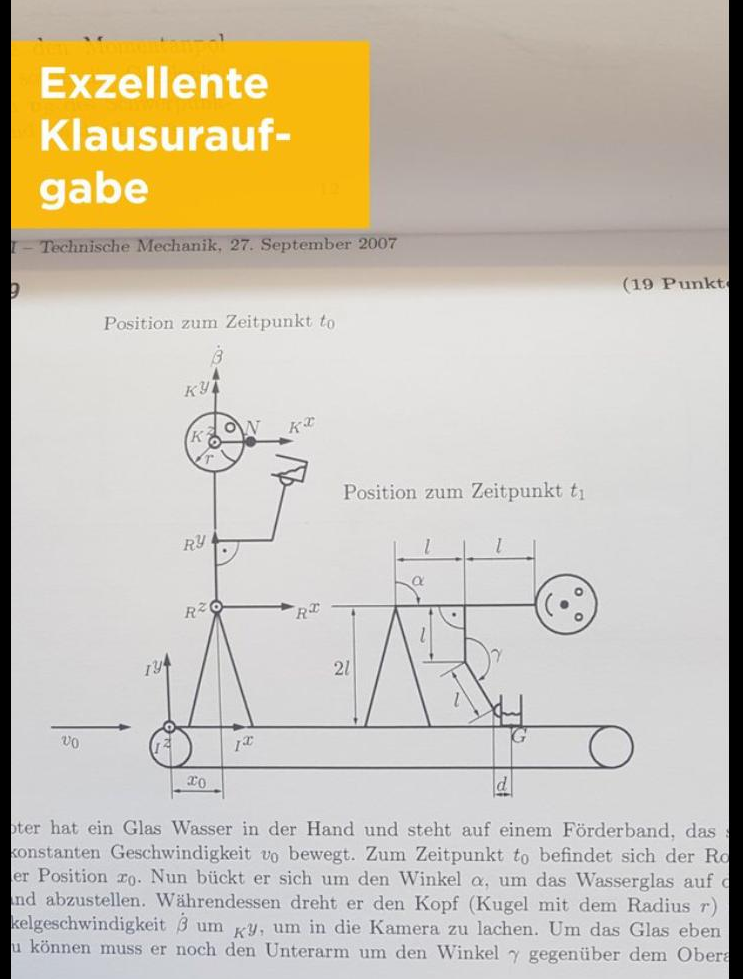

Moment =  Hebelarm x Kraft

"Der Momentenvektor um einen Bezugspunkt ist das Kreuzprodukt aus dem Positionsvektor des Angriffspunktes der Kraft (bzgl des Bezugspunkts) und dem Kraftvektor"

Berechnet den Momentenvektor. 

kraft = [1,2,3];
hebelarm = [1,4,1];

moment = momentenberechnung(kraft, hebelarm)


moment =

     []



## 4) Primzahlerkennung

Schreibt eine Funktion die angibt ob ein input eine Primzahl ist.

- der input `testzahl` soll eine beliebige Zahl >= 3 sein

- der output `istprimzahl` gibt an ob der input eine Primzahl ist. ja -> `istprimzahl = 1`, nein -> `istprimzahl = 0`

Tipp: Das Residuum einer ganzzahligen Division erhält man mit der Modulo-Funktion

testzahl = 7; 
istprimzahl = PrimzahlCheck(testzahl)


istprimzahl =

     []



## 5) Fibonacci-Folge

Implementiert `berechneFibonacci` als **rekursive** Funktion, welche die n-te Zahl $f_n$ in der Fibonacci-Folge ausgibt. Dabei soll gelten:

- n = 1: $f_1 =1$

- n = 2: $f_2 =1$

- n >= 3: $f_n =f_{n-1} +f_{n-2}$

n = 8; 
fib = berechneFibonacci(n)


fib =

     []



## 6) Buchstabensalat

Schreibt eine Funktion die ein Wort "durchmischt":

'altsa' = Buchstabensalat('salat')

Tipps:

- Nutzt den `randperm` Befehl

- Zeichenketten können wie normale Vektoren indiziert werden. Bsp: `Wort = 'Bier'; Wort(3) -> 'e'`

Wort = 'CultureOfExcellence';
Salat =  Buchstabensalat(Wort)


Salat =

     []



## 7) Monte Carlo

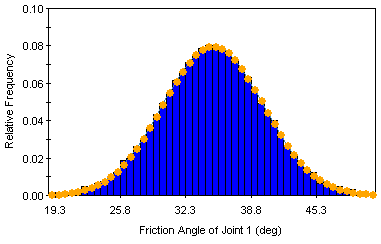

Eine Normalverteilung wird über den Mittelwert und die Varianz (bzw. Standardabweichung) definiert. Erstellt in der Funktion MonteCarlo für vorgegebenen Mittelwert und Varianz eine Normalverteilung. Erstellt dann einen Vektor aus Zufallsvariablen, die der erstellten Wahrscheinlichkeitsverteilung folgen und berechnet mit MATLAB-Funktionen umgekehrt aus diesem Vektor wieder den Mittelwert und die Varianz. Mehr Hinweise findet ihr in der Funktion `MonteCarlo`.

Mittelwert = 10;
Varianz = 2;
[Mittelwert_approx,Varianz_approx] = MonteCarlo(Mittelwert,Varianz)


Mittelwert_approx =

     []


Varianz_approx =

     []



## 8) Weihnachtsbaum

Öffnet das folgende Skript und plottet einen leuchtenden Weihnachtsbaum!

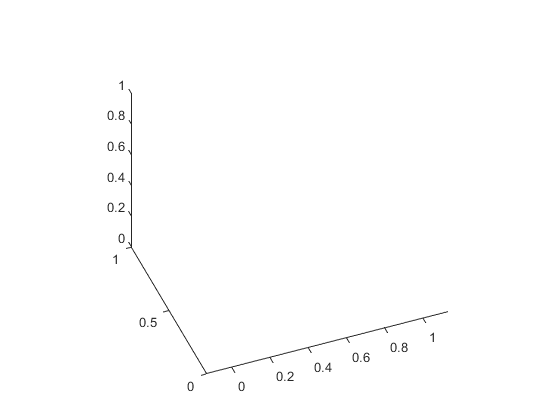

Weihnachtsbaum

## 9) Object Detection

Jetzt wird's interaktiver: In dieser Aufgabe nutzt ihr euer Smartphone und ein vortrainiertes künstliches neuronales Netzwerk, um Objekte zu klassifizieren. Diese Aufgabe ist nur als Spielerei gedacht. Eventuell funktioniert das Programm auch nicht bei jedem. Probiert es einfach mal aus! Seid nicht all zu sehr überrascht, wenn eine Gabel als Pfannenwender erkannt wird :D

- Im Ordner der Olympiade befindet sich auch der Ordner "ObjectDetection"

- Loggt euch im Browser in MATLAB-Drive [drive.matlab.com](https://drive.matlab.com) (die Cloud von Mathworks) oder MATLAB-Online [matlab.mathworks.com](https://matlab.mathworks.com/) ein (mit eurem eigenen MATLAB-Account ab12xyz@matlab.rbg.tum.de) und ladet dort den Ordner ObjectDetection hoch

- Ladet aus dem App/Play-Store die "MATLAB Mobile" App

- Loggt euch mit eurem MATLAB-Account ein

- Im Menü unter "Sensors" > "More": aktiviert "Sensor Access" und "Camera Access"

- In der MATLAB Mobile App seht ihr diesen Ordner nun im Menü unter "Files". Geht in den Ordner und öffnet das Skript "detectObject"

- Führt das Skript aus, indem ihr oben auf das Dreieck tippt. 

- Ihr seht dann eine Kamera-Oberfläche: Macht ein Foto von den unten geforderten Objekten. 

- Das Skript gibt dann aus, welches Objekt erkannt wurde. Gleichzeitig gibt das Skript noch einen Teil des Schlüsselworts aus, falls es sich um eines der geforderten Objekte handelt

- Um ein weiteres Objekt zu erkennen, startet einfach das Skript neu

Schreibt die Schlüsselwörter von den folgenden Objekten in der selben Reihenfolge ohne Leerzeichen zusammen:

- Kugelschreiber

- Tasse

- Schuh

- Flasche

keyword = '';

## Ergebnis

functionCheck()

	1)gruppenalter:			wrong
	2) rollTheDice:			wrong
	3) momentenberechnung:		wrong
	4) PrimzahlCheck:		wrong
	5) fibonacci:			wrong
	6) Buchstabensalat:		wrong
	7) MonteCarlo:			wrong
	8) Weihnachtsbaum:		richtig nur wenn ein schöner weihnachtsbaum erscheint :) 
	9) ObjectDetection:		wrong
